# 4.7 Design a SS controller selecting the poles using the LQR technique

load Linear_Param.mat
Cweight = [20 5 10 1]; %Most weight on theta_b, less on wheel
B1 = B(:,1);
[num,den] = ss2tf(A,B1,Cweight,0)

num = 1.0e+04 *

         0    0.0013   -0.0489   -0.3635   -1.4540


den = 1.0e+04 *

    0.0001    0.0475   -0.0062   -1.5371         0


s = tf("s");
Nplus = num(1)*(s)^4 +num(2)*(s)^3 +num(3)*(s)^2 +num(4)*(s)^1 +num(5)*(s)^0;
Nminus = num(1)*(-s)^4 +num(2)*(-s)^3 +num(3)*(-s)^2 +num(4)*(-s)^1 +num(5)*(-s)^0;
Dplus = den(1)*(s)^4 +den(2)*(s)^3 +den(3)*(s)^2 +den(4)*(s)^1 +den(5)*(s)^0;
Dminus = den(1)*(-s)^4 +den(2)*(-s)^3 +den(3)*(-s)^2 +den(4)*(-s)^1 +den(5)*(-s)^0;
sysGG = Nplus*Nminus/(Dplus*Dminus)

sysGG =
 
  -165.2 s^6 + 3.323e05 s^4 - 5.821e-11 s^3 + 9.995e05 s^2 + 2.114e08
  -------------------------------------------------------------------
           s^8 - 2.258e05 s^6 + 1.461e07 s^4 - 2.363e08 s^2
 
Continuous-time transfer function.
Model Properties


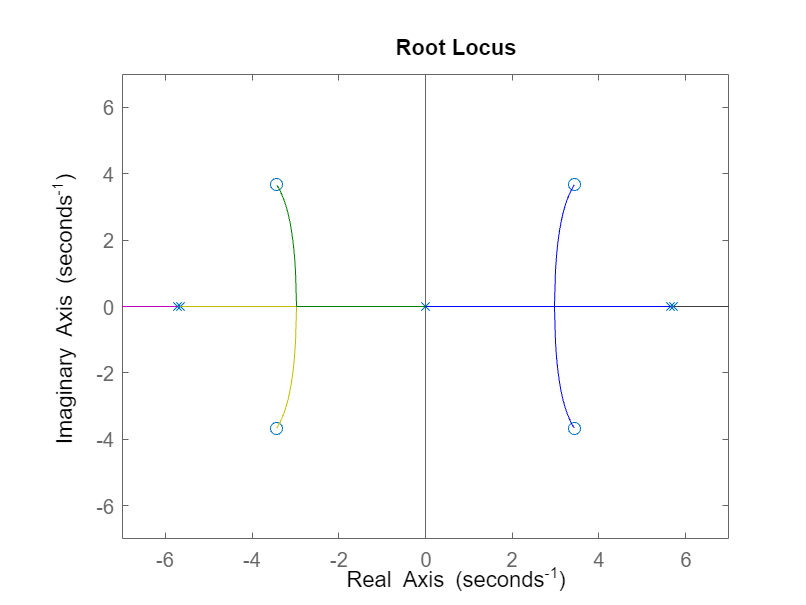



rlocus(sysGG)
% xaxis(-7,7)
xlim([-7 7])
% yaxis(-7,7)
ylim([-7 7])

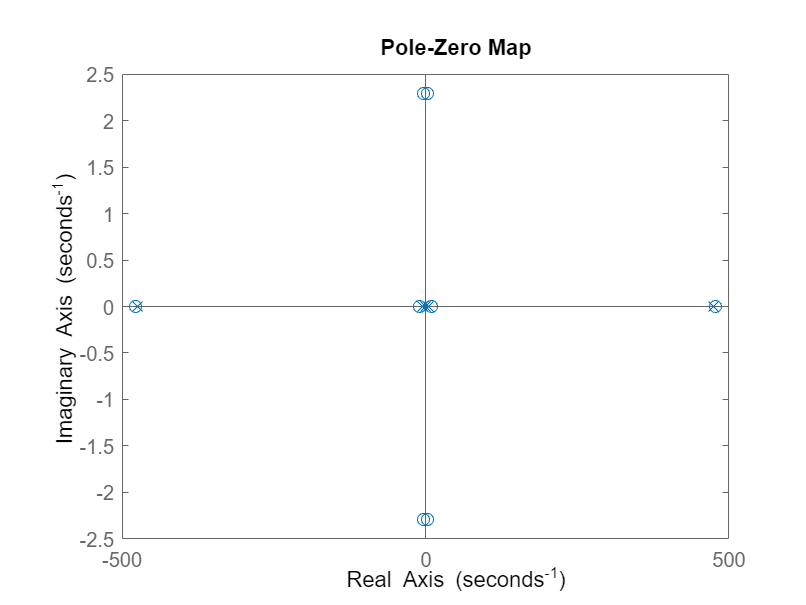

rhoChose = 20;
  pzmap(1+rhoChose*sysGG)

poles =  zero(1+rhoChose*sysGG);
format shortE
stablePoles = poles(real(poles)<0)

stablePoles =   -4.7850e+02 + 0.0000e+00i
  -9.1764e+00 + 0.0000e+00i
  -3.0916e+00 + 2.2916e+00i
  -3.0916e+00 - 2.2916e+00i


K = acker(A,B1,stablePoles)

K =   -8.9443e+01  -6.8421e+01  -1.0356e+02  -1.5847e+01


poles = stablePoles;
save("poles.mat","poles")

%Testing to see right K achieved
Q = rhoChose*Cweight'*Cweight

Q =         8000        2000        4000         400
        2000         500        1000         100
        4000        1000        2000         200
         400         100         200          20


R = 1

R =      1


K = lqr(A,B1,Q,R)

K =   -8.9443e+01  -6.8421e+01  -1.0356e+02  -1.5847e+01



Q = zeros(4);
Q(1,1) = 1/0.05^2;
Q(2,2) = 0;
Q(3,3) = 1/0.5^2

Q =    4.0000e+02            0            0            0
            0            0            0            0
            0            0   4.0000e+00            0
            0            0            0            0


Q(4,4) = Q(3,3)

Q =    4.0000e+02            0            0            0
            0            0            0            0
            0            0   4.0000e+00            0
            0            0            0   4.0000e+00


R = 1/8^2

R =    1.5625e-02


K = lqr(A,B1,Q,R)

K =   -1.6000e+02  -1.1399e+02  -2.0696e+02  -3.7736e+01
